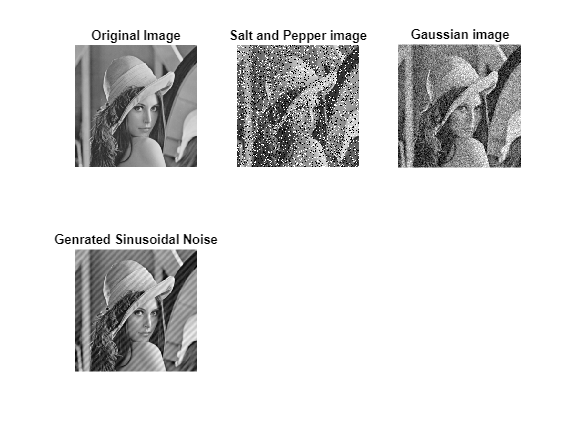

clc
close all
mygrayimg = imread('lena_gray.jpeg');
mygrayimg = imresize(mygrayimg,[256 256], 'bilinear');
subplot(2,3,1);
imshow(mygrayimg);
title('Original Image');

salt = imnoise(mygrayimg,  'salt & pepper', 0.2);
subplot(2,3,2);
imshow(salt);
title("Salt and Pepper image");

gau = imnoise(mygrayimg,"gaussian",0,0.01);
subplot(2,3,3);
imshow(gau);
title("Gaussian image");

subplot(2,3,4);
[x y]= meshgrid(1:256,1:256);
mysinusoidalnoise =15*sin(2*pi/14*x+2*pi/14*y);
mynoiseimg1 = double(mygrayimg)+ mysinusoidalnoise;
imshow(mynoiseimg1,[]);
title("Genrated Sinusoidal Noise");